load('large_theta_-3.1416(rad)_fx_-2.45e-17_fy_-0.2_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau.mat');


% load('large_theta_-3.1416(rad)_fx_-2.45e-17_fy_-0.2_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau.mat')
load('large_theta_-2.0944(rad)_fx_-0.173_fy_-0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau.mat')

load('large_theta_-2.618(rad)_fx_-0.1_fy_-0.173_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau.mat');

filename='fx_0.02_fy_0.01_fxy_0_tauc_0_xc_0_yc_0_freq_2_nonAvgIqtau.mat';


freq=2;
time_step=0.1;
% 2*pi*freq*time_step*double(t)
T=1/(freq*time_step)


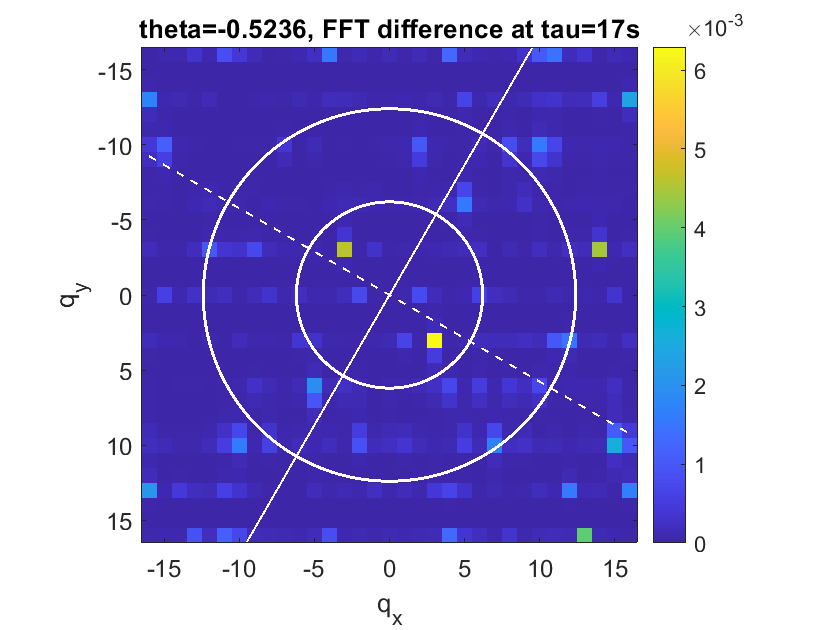

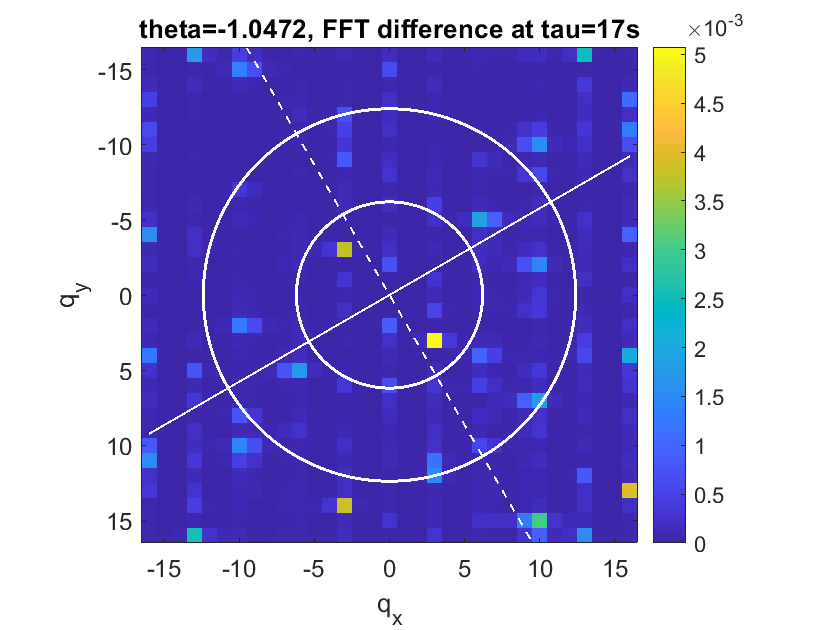

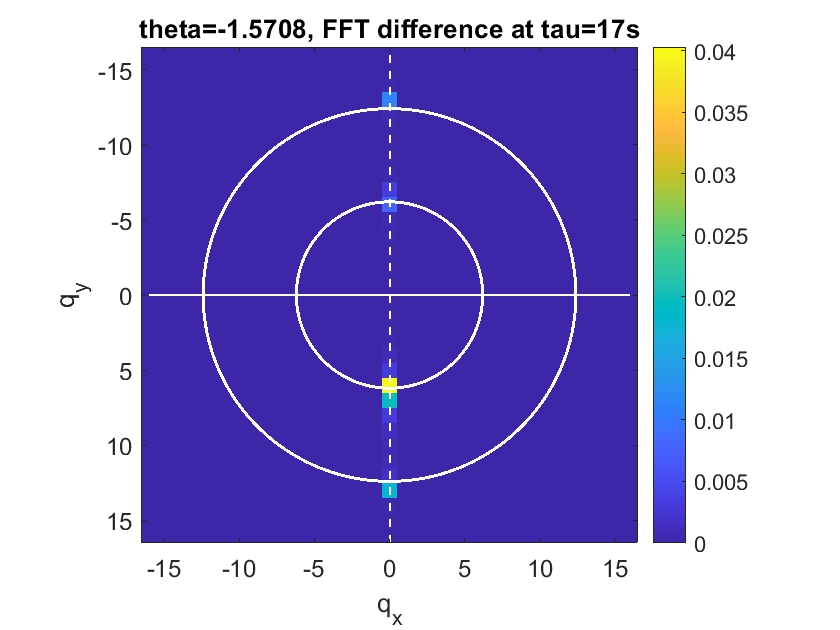

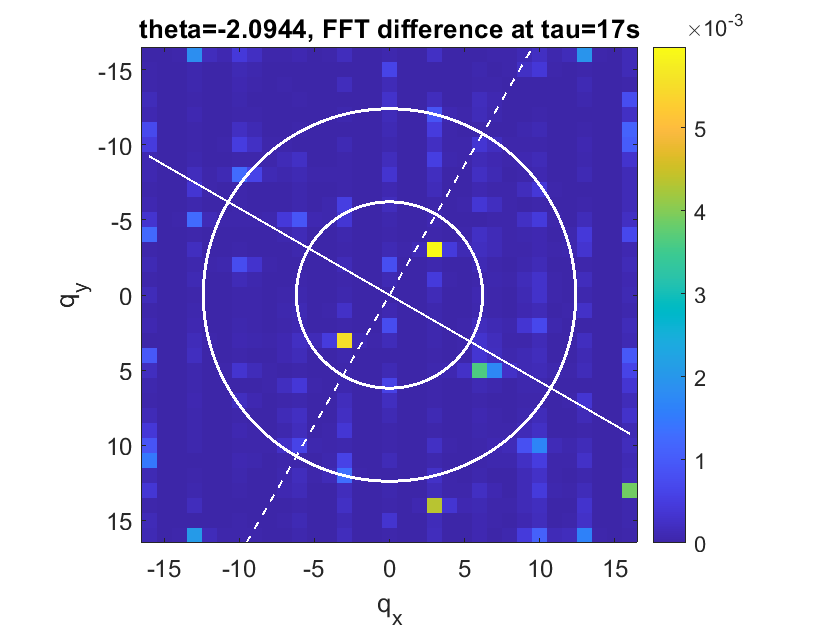

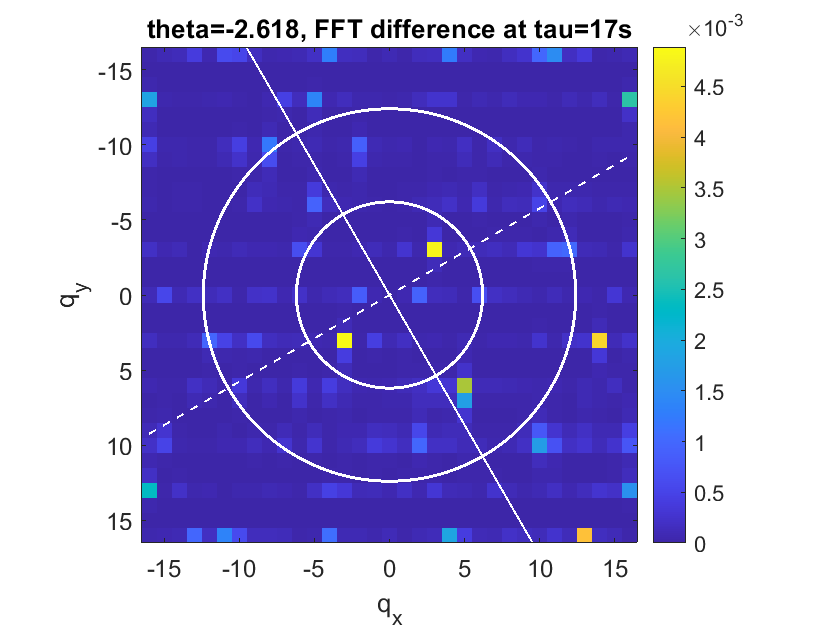

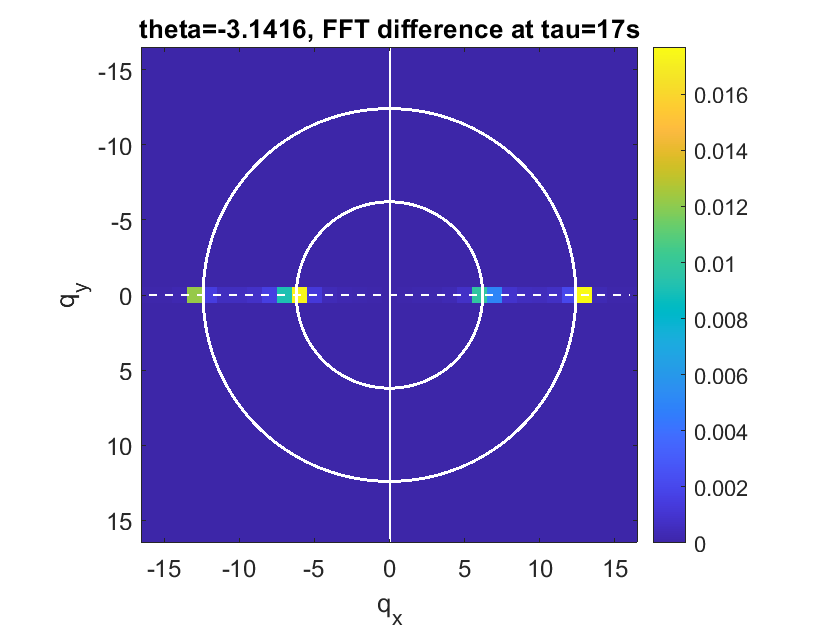

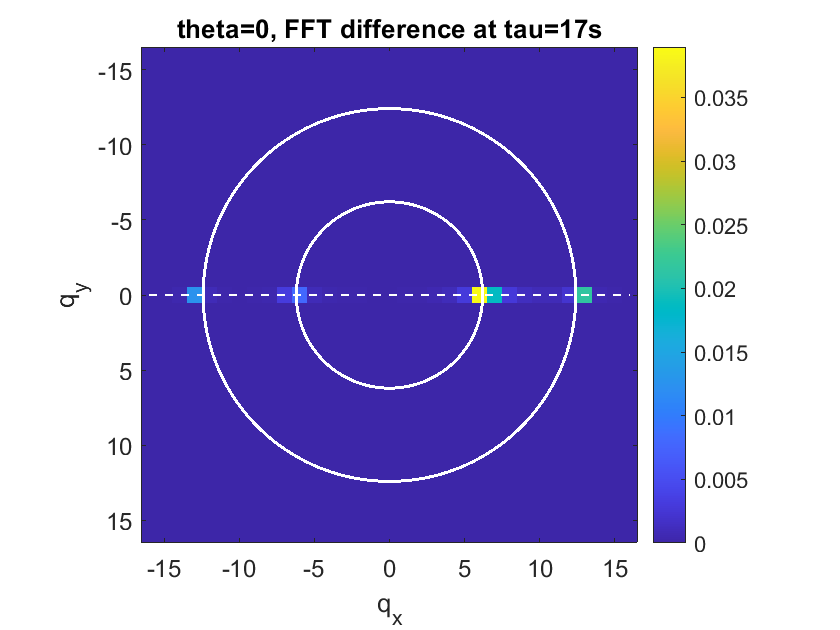

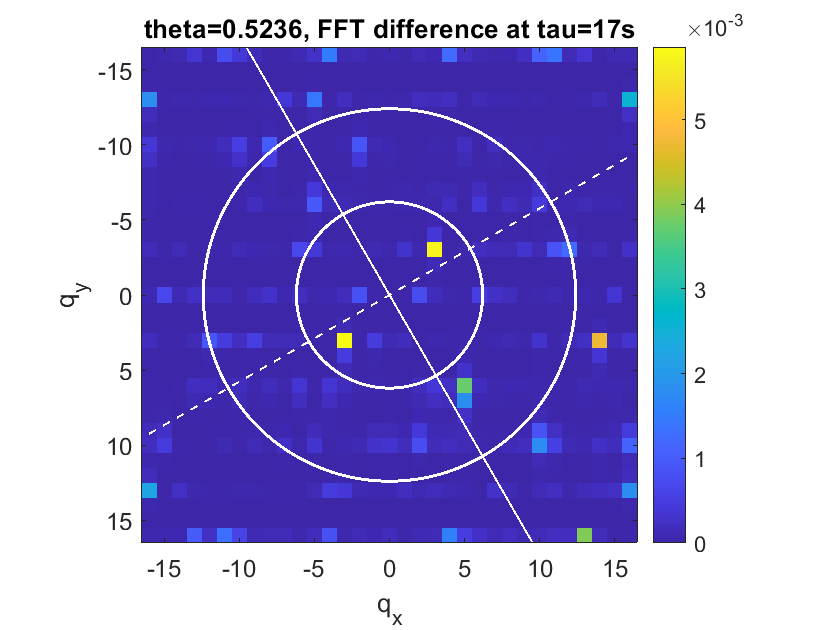

clc
clear
path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\direction_plots\';    
% path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\make_synthetic_video\videos_for_direction_wavelength_analysis_Analysis\plots\';
% path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\wavelength_plots\';
% filename='large_theta_-2.618(rad)_fx_-0.1_fy_-0.173_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau.mat';
q_range=16;
tau=17;

scale=512;


files = dir('*_nonAvgIqtau.mat');

N_grid=31;
for file = files'
    filename=file.name;
%     plotFFTdifference_pixelVideos(filename,scale,N_grid,q_range,tau,path)
%     plotFFTdifference(filename,num_of_wave_on_diagonal,scale,q_range,tau,path);
    plotFFTdifference_pixelVideos_with_theta(filename,scale,N_grid,q_range,tau,path);
end

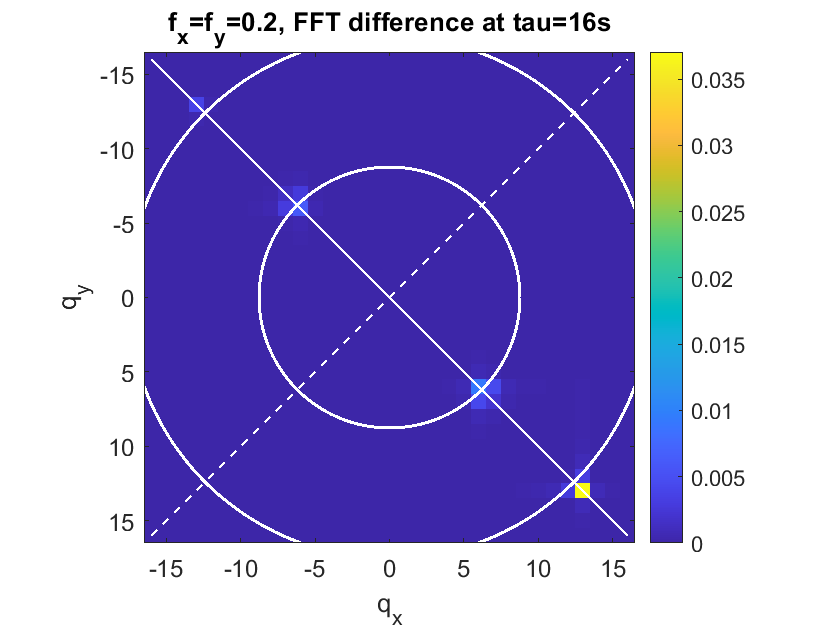

q_range=16;
plotFFTdifference_pixelVideos(filename,scale,N_grid,q_range,tau,path)

filename='large_fx_0.05_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau.mat';
num_of_wave_on_diagonal=4;
plotFFTdifference(filename,num_of_wave_on_diagonal,scale,q_range,tau,path);

viscircles([0,0],num_of_wave_on_diagonal/sqrt(2),'Color','none','LineStyle','--','LineWidth',1);

imagesc(sum(nonAvgIqtau(radius+1-q_range:radius+1+q_range,radius+1-q_range:radius+1+q_range,:),3), 'XData', [-q_range q_range], 'YData', [-q_range q_range]);

function []=plotFFTdifference(filename,num_of_wave_on_diagonal,scale,q_range,tau,path)
    data=load(filename);
    filename_split=split(filename,'_');
    theta=char(filename_split(3));
    theta=theta(1:end-5);
    theta=str2double(theta);
%     theta=pi/4;
    
    filename_split=split(filename,'_');
    fx=char(filename_split(3));
       
    radius=scale/2+1;
    fig=figure();
    data.nonAvgIqtau(radius,radius,tau)=0;
    imagesc(data.nonAvgIqtau(radius-q_range:radius+q_range,radius-q_range:radius+q_range,tau), 'XData', [-q_range q_range], 'YData', [-q_range q_range]);
    hold on;
    x = -q_range:0.1:q_range;
    y = x*tan(-theta);
    z = x/tan(theta);
    plot(x,y,'LineStyle','--','Color','white','LineWidth',1,'Tag','perpendicular')
    plot(x,z,'LineStyle','-','Color','white','LineWidth',1,'Tag','direction')
    hold on;
    viscircles([0,0],num_of_wave_on_diagonal/sqrt(2),'Color','none','LineStyle','--','LineWidth',0.5);
    % text(x(end),y(end),'perpendicular');
    set(gca,'dataAspectRatio',[1 1 1])
    colorbar;
    xlabel('q_x');
    ylabel('q_y');
%     title(['theta=' num2str(theta) ', FFT difference at tau=' num2str(tau) 's'])
    title(['f_x=f_y=' fx ', FFT difference at tau=' num2str(tau) 's'])
    set(gca,'fontsize', 12);
    
    saveas(fig,[path filename(1:end-4) '_FFTdifference_plot.png']);
end

function []=plotFFTdifference_pixelVideos(filename,scale,N_grid,q_range,tau,path)
    data=load(filename);
    filename_split=split(filename,'_');
    fx=str2double(filename_split(3));
    fy=str2double(filename_split(5));
    
    Tx=1/fx;   % period in dots
    Ty=1/fy;
    Px=N_grid/Tx;  % wavenumber
    Py=N_grid/Ty;
    
    circle_rad=sqrt(Px^2+Py^2);
%     circle_rad=Px+Py;

    theta=atan(fx/fy);
%     theta=char(filename_split(3));
%     theta=theta(1:end-5);
%     theta=str2double(theta);
%     theta=pi/4;
    
       
    radius=scale/2+1;
    fig=figure();
    data.nonAvgIqtau(radius,radius,tau)=0;
    imagesc(data.nonAvgIqtau(radius-q_range:radius+q_range,radius-q_range:radius+q_range,tau), 'XData', [-q_range q_range], 'YData', [-q_range q_range]);
    hold on;
    x = -q_range:0.1:q_range;
    y = x*tan(-theta);
    z = x/tan(theta);
    plot(x,y,'LineStyle','--','Color','white','LineWidth',1,'Tag','perpendicular')
    plot(x,z,'LineStyle','-','Color','white','LineWidth',1,'Tag','direction')
    hold on;
    viscircles([0,0],circle_rad,'LineStyle','-.','Color','white','LineWidth',0.5);
    viscircles([0,0],2*circle_rad,'LineStyle',':','Color','white','LineWidth',0.5);
    % text(x(end),y(end),'perpendicular');
    set(gca,'dataAspectRatio',[1 1 1])
    colorbar;
    xlabel('q_x');
    ylabel('q_y');
%     title(['theta=' num2str(theta) ', FFT difference at tau=' num2str(tau) 's'])
    title(['f_x=f_y=' num2str(fx) ', FFT difference at tau=' num2str(tau) 's'])
    set(gca,'fontsize', 12);
    
    saveas(fig,[path filename(1:end-4) '_FFTdifference_plot.png']);
end

function []=plotFFTdifference_pixelVideos_with_theta(filename,scale,N_grid,q_range,tau,path)
    data=load(filename);
    filename_split=split(filename,'_');
    fx=str2double(filename_split(5));
    fy=str2double(filename_split(7));
    
    Tx=1/fx;   % period in dots
    Ty=1/fy;
    Px=N_grid/Tx;  % wavenumber
    Py=N_grid/Ty;
    
    circle_rad=sqrt(Px^2+Py^2);
%     circle_rad=Px+Py;

%     theta=atan(fx/fy);
    theta=char(filename_split(3));
    theta=theta(1:end-5);
    theta=str2double(theta);
%     theta=pi/4;
    
       
    radius=scale/2+1;
    fig=figure();
    data.nonAvgIqtau(radius,radius,tau)=0;
    imagesc(data.nonAvgIqtau(radius-q_range:radius+q_range,radius-q_range:radius+q_range,tau), 'XData', [-q_range q_range], 'YData', [-q_range q_range]);
    hold on;
    x = -q_range:0.1:q_range;
    y = x*tan(-theta);
    z = x/tan(theta);
    plot(x,y,'LineStyle','--','Color','white','LineWidth',1,'Tag','perpendicular')
    plot(x,z,'LineStyle','-','Color','white','LineWidth',1,'Tag','direction')
    hold on;
    viscircles([0,0],circle_rad,'LineStyle','-.','Color','white','LineWidth',0.5);
    viscircles([0,0],2*circle_rad,'LineStyle',':','Color','white','LineWidth',0.5);
    % text(x(end),y(end),'perpendicular');
    set(gca,'dataAspectRatio',[1 1 1])
    colorbar;
    xlabel('q_x');
    ylabel('q_y');
    title(['theta=' num2str(theta) ', FFT difference at tau=' num2str(tau) 's'])
%     title(['f_x=f_y=' num2str(fx) ', FFT difference at tau=' num2str(tau) 's'])
    set(gca,'fontsize', 12);
    
    saveas(fig,[path filename(1:end-4) '_FFTdifference_plot.png']);
end
